# Read Spreadsheet Data into Table 

This example shows how to import mixed numeric and text data from a spreadsheet into a table. MATLAB® tables store both the data and relevant supporting information such as variable names or row names, all in a single container. You can import all the data in the worksheet or import only a subset of interest.

## Preview the Data 

Open the file `airlinesmall_subset.xlsx` and preview its contents in a spreadsheet application like Excel®.  To locate the file, type '`which airlinesmall_subset.xlsx`' in the command window. The data in the file comes from USA domestic airline flights between `1996` and `2008`. The information is organized in multiple worksheets, where each sheet contains data for `1` year. The screenshot here shows only the first 10 rows and columns from the worksheet titled `1996`.  

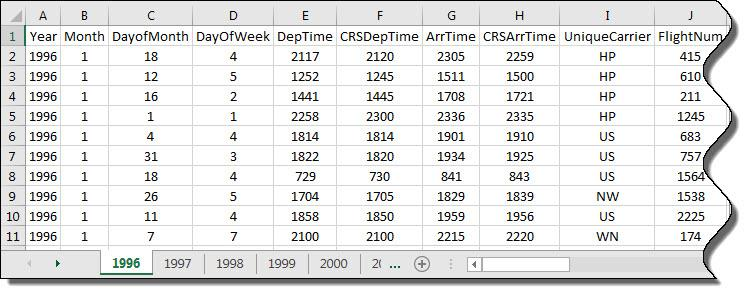

## Read All Data from Worksheet

Call `readtable` to read all the data in the worksheet called `1996 `and display only the first 10 rows and columns. Specify the worksheet name using the `Sheet` name-value pair argument. If your data is on the first worksheet in the file, you do not need to specify `Sheet`. 

T = readtable('airlinesmall_subset.xlsx','Sheet','1996');
T(1:10,1:10)

## Read Selected Range from Worksheet

Read only 10 rows of data from the first 3 columns by specifying a range, `'A1:C11'`. The `readtable` function returns a 10-by-3 table.

T_selected = readtable('airlinesmall_subset.xlsx','Sheet','1996','Range','A1:C11')

## Read All Worksheets from Spreadsheet File

Import all the worksheets from an Excel® file. You can get the names of all the worksheets and display the total number of spreadsheets contained in the file. On a Windows® system with Excel® installed, you can use `xlsfinfo` to get the sheet names. 

[~,SheetNames]  = xlsfinfo('airlinesmall_subset.xlsx')
nSheets = length(SheetNames)

Import the worksheets, one at a time, and organize them in a structure array `S`. The size of `S `corresponds to the number of worksheets in the file, which is `13`. For instance, import the first worksheet into `S(1).Data`, the second worksheet into `S(2).Data,` and the last worksheet into `S(nSheets).Data`. 

 for iSheet = 1:nSheets
  Name = SheetNames{iSheet}; 
  Data = readtable('airlinesmall_subset.xlsx','Sheet',Name) ; 
  S(iSheet).Name = Name;
  S(iSheet).Data = Data;
 end

To view the data, index into the structure array. For example, retrieve the name and first 10 rows and columns from the first worksheet and verify if they match the data in the spreadsheet.

 S(1).Name
 S(1).Data(1:10,1:10)

From the first worksheet, get the variable `ArrDelay `which captures the arrival delay in minutes for the year `1996`. Then, compute maximum arrival delay for that year. 

    ArrDelay = S(1).Data.ArrDelay; 
    maxDelay = max(ArrDelay);
    maxDelayInHours = maxDelay/60

*Copyright 2012 The MathWorks, Inc.*